# Elaborato

Lazzaro Francesco 220810

## Traccia

Si vuole progettare il modello dinamico di un Robot industriale così composto:

- 2 bracci $L_1$ ed $L_2$ entrambi di lunghezza $1\;m$

- 2 giunti rotoidali, $q_1$ che collega $L_1$ alla base del robot e $q_2$ che collega $L_1$ed $L_2$

- $L_1$ ed $L_2$ hanno una massa pari ad $1\;\textrm{Kg}$

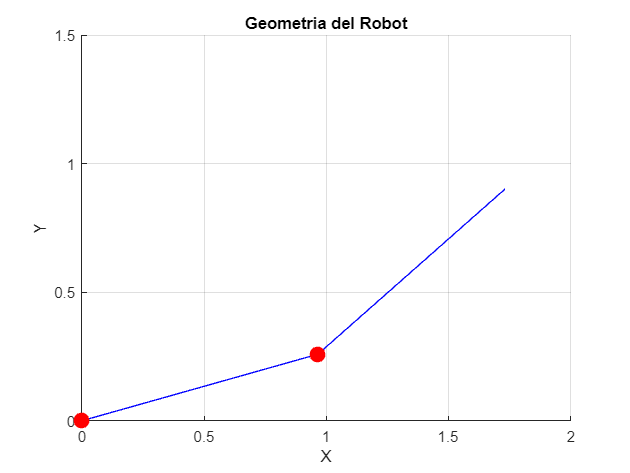

% Lunghezza dei segmenti
lunghezza = 1;

% Angoli dei segmenti (in radianti)
angolo_l1 = deg2rad(15); % Angolo del primo segmento (rispetto all'asse x)
angolo_l2 = deg2rad(40); % Angolo del secondo segmento (rispetto all'asse x)

% Calcolo delle coordinate dei punti terminali dei segmenti
x_origine = 0;
y_origine = 0;

x_l1 = lunghezza * cos(angolo_l1);
y_l1 = lunghezza * sin(angolo_l1);

x_l2 = x_l1 + lunghezza * cos(angolo_l2);
y_l2 = y_l1 + lunghezza * sin(angolo_l2);

% Disegno dei segmenti
figure;
hold on;
plot([x_origine, x_l1], [y_origine, y_l1], 'b'); % Disegna il primo segmento
plot([x_l1, x_l2], [y_l1, y_l2], 'b'); % Disegna il secondo segmento

% Segna i punti di contatto
plot(x_origine, y_origine, 'ro', 'MarkerSize', 10, 'MarkerFaceColor', 'r'); % Origine
plot(x_l1, y_l1, 'ro', 'MarkerSize', 10, 'MarkerFaceColor', 'r'); % Estremità del primo segmento

% Impostazioni dell'asse
axis([0 2 0 1.5]); % Imposta i limiti dell'asse x e y positivi
xlabel('X');
ylabel('Y');
title('Geometria del Robot');

% Mostra la griglia
grid on;

Il robot deve seguire un percorso così composto:

- Dal punto $P_1 =\left(0\ldotp 5,0\ldotp 5\right)$ al tempo $t=0$ si sposta nel punto $P_2 =\left(1\ldotp 5,0\ldotp 5\right)$ al tempo $t=10s$ seguendo un percorso a minima distanza

- Rimane fermo per $5s$

- Dal punto $P_2$ al tempo $t=15s$ si sposta nel punto $P_1$ al tempo $t=30s$ seguendo un percorso semicircolare con centro in $c=\left(1,0\ldotp 5\right)$ e raggio $r=0\ldotp 5$

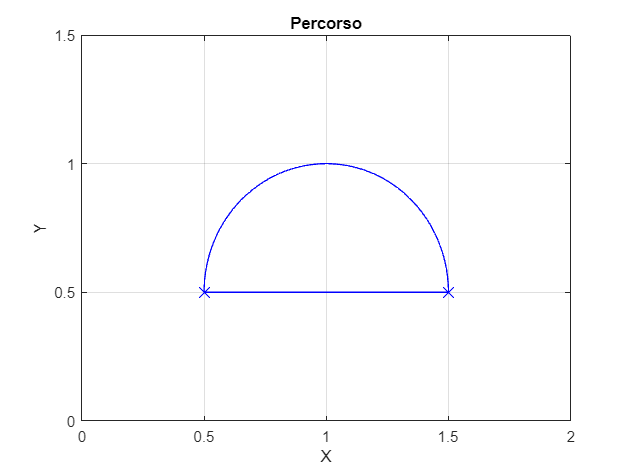

% Definisci il centro e il raggio del semicerchio
figure;
centro = [1, 0.5];
raggio = 0.5;

% Calcola gli angoli iniziali e finali per disegnare il semicerchio
theta_iniziale = 0;
theta_finale = pi;

% Genera un vettore di angoli per disegnare il semicerchio
theta = linspace(theta_iniziale, theta_finale, 100);

% Calcola le coordinate x e y dei punti lungo il semicerchio
x = centro(1) + raggio * cos(theta);
y = centro(2) + raggio * sin(theta);

% Definisci i punti P1 e P2
p1 = [0.5, 0.5];
p2 = [1.5, 0.5];

% Disegna il semicerchio e i punti P1 e P2
plot(x, y, 'b');
hold on;
plot(p1(1), p1(2), 'bx', 'MarkerSize', 10);
plot(p2(1), p2(2), 'bx', 'MarkerSize', 10);

% Disegna il segmento che collega P1 e P2
plot([p1(1), p2(1)], [p1(2), p2(2)], 'b', 'LineWidth', 1);

axis([0 2 0 1.5]); 
grid on;
xlabel('X');
ylabel('Y');
title('Percorso');

L'obiettivo è generare un modello che minimizzi l'errore di posizione rispetto al percorso

## Percorso a minima distanza 1)

### Legge oraria e Generatore di riferimento

Parametrizzando l'equazione che descrive la traiettoria si ottiene $P\left(\lambda \right)=P_1 +\lambda \left(P_2 -P_1 \right)=\left\lbrack \begin{array}{c}
x\left(\lambda \right)\\
y\left(\lambda \right)
\end{array}\right\rbrack \textrm{con}\;0\le \lambda \le 1$

$\lambda =\lambda \left(t\right)$  e inoltre si può riscrivere l'equazione come $P\left(\lambda \left(\sigma \right)\right)=P_1 +\lambda \left(\sigma \right)\left(P_2 -P_1 \right)\;\textrm{con}\;\sigma =\frac{t-T_1 }{T_2 -T_1 }$

Si rende necessario per ottenere un andamento realistico della posizione e della velocità usare una funzione $\lambda$del tipo $\lambda \left(\sigma \right)=-2\sigma^3 +3\sigma^2$.

Sviluppando le equazioni si ottengono:

$P\left(t\right)=\left\lbrack \begin{array}{c}
x\left(t\right)\\
y\left(t\right)
\end{array}\right\rbrack$=$\left\lbrack \begin{array}{c}
P_{1\;x} +\left(-2{\left(\frac{t-T_1 }{T_2 -T_1 }\right)}^3 +3{\left(\frac{t-T_1 }{T_2 -T_1 }\right)}^2 \right)\left(P_{2\;x} -P_{1\;x} \right)\\
P_{1\;y} 
\end{array}\right\rbrack$    da cui    $\dot{P\left(t\right)} \;=\left\lbrack \begin{array}{c}
\dot{x\left(t\right)} \\
\dot{y\left(t\right)} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
\frac{1}{T_2 -T_1 }\left(-6{\left(\frac{t-T_1 }{T_2 -T_1 }\right)}^2 +6\left(\frac{t-T_1 }{T_2 -T_1 }\right)\right)\left(P_{2\;x} -P_{1\;x} \right)\\
0
\end{array}\right\rbrack$

(per le successive rappresentazioni: colore blu primo braccio, colore rosso secondo braccio)

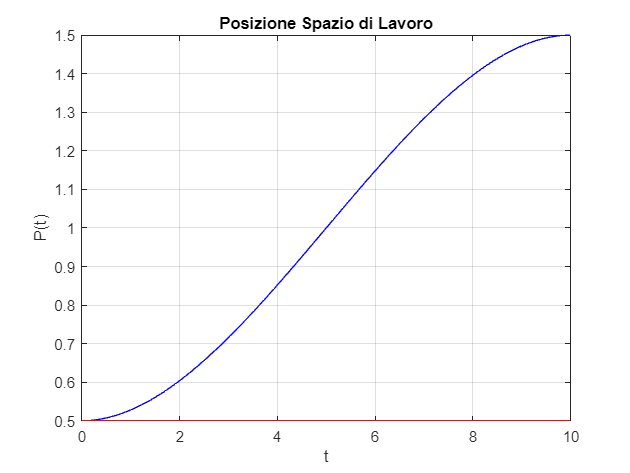

% Definizione dei punti P1 e P2
P1 = [0.5, 0.5];
P2 = [1.5, 0.5];

% Definizione dei tempi T1 e T2
T1 = 0;
T2 = 10;

% Definizione delle lunghezze L1 e L2
L1 = 1;
L2 = 1;

% Generazione di valori di t da 0 a 10
t = linspace(T1, T2, 100); % Esempio con 100 valori

%Generazione lambda e sigma
sigma = (t - T1) / (T2 - T1);

lambda=-2*sigma.^3+3*sigma.^2;

%% Calcoli delle funzioni spazio e velocità per ogni valore di t
% Inizializzazione dei vettori per i risultati
x = zeros(size(t)); y = zeros(size(t));
vx = zeros(size(t)); vy = zeros(size(t));
ax = zeros(size(t)); ay = zeros(size(t));
c2 = zeros(size(t)); s2 = zeros(size(t));
c1 = zeros(size(t)); s1 = zeros(size(t));
q1 = zeros(size(t)); q2 = zeros(size(t));
dq1 = zeros(size(t)); dq2 = zeros(size(t));
ddq1 = zeros(size(t)); ddq2 = zeros(size(t));

% Calcolo dei valori per ogni valore di t
for i = 1:numel(t)
    % Calcoli delle funzioni posizione
    x(i) = P1(1) + lambda(i) * (P2(1) - P1(1));
    y(i) = P1(2);

    % Calcoli delle funzioni velocità
    vx(i) = ((-6*sigma(i)^2) +6*sigma(i))*(1 / (T2 - T1)) * (P2(1) - P1(1));
    vy(i) = 0;

    % Calcolo accelerazione
    ax(i) = ((-12*sigma(i)) +6)*(1 / (T2 - T1))^2 * (P2(1) - P1(1));
    ay(i) = 0;

    % Cinematica inversa     
    %Calcolo di q2  
    c2(i) = (x(i)^2 + y(i)^2 - L1^2 - L2^2) / (2 * L1 * L2);
    s2(i) = sqrt(1 - c2(i)^2);
    q2(i) = atan2(s2(i), c2(i));
    
    % Calcolo di q1
    A=[L1+L2*c2(i) -L2*s2(i); 
    L2*s2(i) (L1+L2*c2(i))];
    Q1=(inv(A))*[x(i);y(i)];
    c1(i)=Q1(1);
    s1(i)=Q1(2);
    q1(i)=atan2(s1(i),c1(i));
end

figure; plot(t,x,'b',t,y,'r');
grid on;
xlabel('t');
ylabel('P(t)');
title('Posizione Spazio di Lavoro');

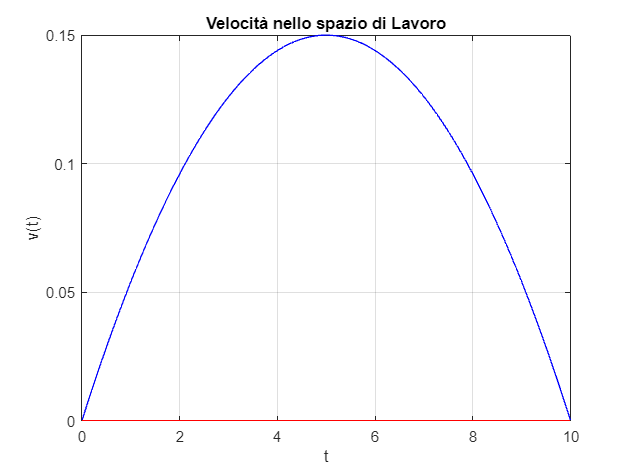



figure; plot(t,vx,'b',t,vy,'r');
grid on;
xlabel('t');
ylabel('v(t)');
title('Velocità nello spazio di Lavoro');

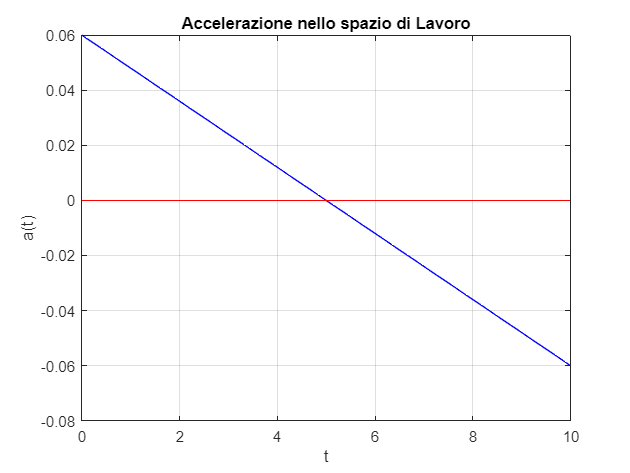


figure; plot(t,ax,'b',t,ay,'r');
grid on;
xlabel('t');
ylabel('a(t)');
title('Accelerazione nello spazio di Lavoro');

### Cinematica inversa

Nella cinematica diretta le equazioni che legano $P\;e\;Q$ sono


$$P_x =L_1 \;c_1 +L_2 \;c_{12}$$
 


$$P_y =L_1 \;s_1 +L_2 \;s_{12}$$


Quadrando e sommando le equazioni si ottiene

 
$$P_x^2 +P_y^2 -\left(L_1^2 +L_2^2 \right)=2L_1 L_2 \left(c_1 c_{12} +s_1 s_{12} \right)=2L_1 L_2 c_2$$


Da cui si ricavano $c_2$ ed $s_2$


$$c_2 =\frac{P_x^2 +P_y^2 -L_1^2 -L_2^2 }{2L_1 L_2 }$$
        
$$s_2 =\pm \sqrt{1-{\left(c_2 \right)}^2 }$$


Pertanto si può stabilire il valore di $q_2$ come $q_2 =\textrm{ATAN2}\left(s_2 ,c_2 \right)$

$q_1$si può ricavare da $q_2$ per ispezione geometrica, oppure risolvendo invece il sistema di equazioni della cinematica diretta per $c_1 \;\textrm{ed}\;s_1$


$$Q_1 =A^{-1} P$$
    
$$\to q_1 =\textrm{ATAN2}\left(s_1 ,c_1 \right)$$


oppure $q_1 =\textrm{ATAN2}\left(P_y ,P_x \right)-\textrm{ATAN2}\left(L_2 s_2 ,L_1 +L_2 c_2 \right)$

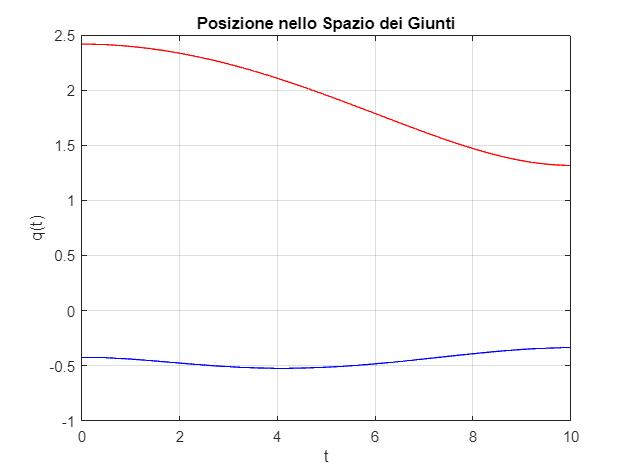

figure; plot(t,q1,'b',t,q2,'r');
grid on;
xlabel('t');
ylabel('q(t)');
title('Posizione nello Spazio dei Giunti');

### Cinematica differenziale inversa

Dalla cinematica differenziale diretta l'equazione che descrive il legame tra $\dot{P} =v\;e\;\dot{Q}$ è

$\dot{P} =J\left(Q\right)\dot{Q}$    dove $J=\left\lbrack \begin{array}{cc}
-L_1 s_1 -L_2 s_{12}  & -L_2 s_{12} \\
L_1 c_1 +L_2 c_{12}  & L_2 c_{12} 
\end{array}\right\rbrack$ 

Lo Jacobiano $J$ è una matrice che descrive come le velocità dei giunti influenzano le velocità di un punto di interesse  nello spazio cartesiano.

$J$ è la matrice delle derivate parziali che collega la velocità delle coordinate articolari $\dot{q}$� alla velocità delle coordinate cartesiane $v$.

Se $J$ ha determinante diverso da zero (invertibile) si può quindi scrivere


$$\dot{Q} =J^{-1} \left(Q\right)\dot{P}$$


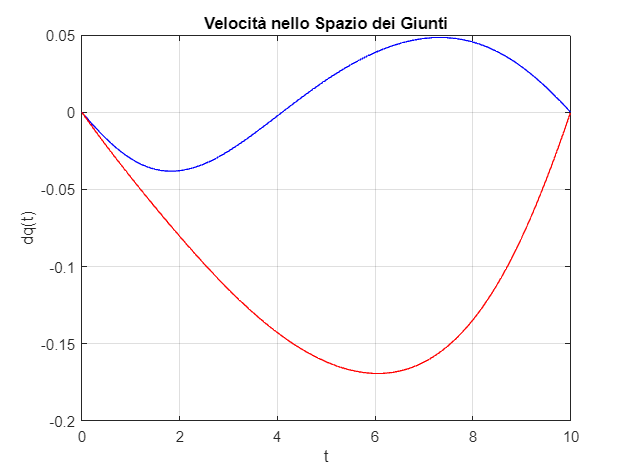

% Cinematica differenziale inversa

for i = 1:numel(t)
    % Calcolo della matrice J
    J = [-L1*sin(q1(i)) - L2*sin(q1(i)+q2(i)), -L2*sin(q1(i)+q2(i));
         L1*cos(q1(i)) + L2*cos(q1(i)+q2(i)), L2*cos(q1(i)+q2(i))];

    % Inversione della matrice J
    J_inv = inv(J);
    v=[vx(i); vy(i)];

    % Moltiplicazione della matrice invertita per il vettore di velocità
    dQ = (J_inv )* v;

    % Estrazione dei valori di dq1 e dq2
    dq1(i) = dQ(1, :);
    dq2(i) = dQ(2, :);

    % Accelerazione
    Jp = [-L1*c1(i)*dq1(i)-L2*cos(q1(i)+q2(i))*(dq1(i)+dq2(i)), -L2*cos(q1(i)+q2(i))*(dq1(i)+dq2(i));
        -L1*s1(i)*dq1(i)-L2*sin(q1(i)+q2(i))*(dq1(i)+dq2(i)), -L2*sin(q1(i)+q2(i))*(dq1(i)+dq2(i))];

    J = [-L1*s1(i)-L2*sin(q1(i)+q2(i)), -L2*sin(q1(i)+q2(i));
        L1*c1(i)+L2*cos(q1(i)+q2(i)), L2*cos(q1(i)+q2(i))];
    b = [ax(i);ay(i)] - Jp*[dq1(i);dq2(i)];
    Qpp = (inv(J))*b;

     ddq1(i) = Qpp(1, :);
    ddq2(i) = Qpp(2, :);

end

figure; plot(t,dq1,'b',t,dq2,'r');
grid on;
xlabel('t');
ylabel('dq(t)');
title('Velocità nello Spazio dei Giunti');

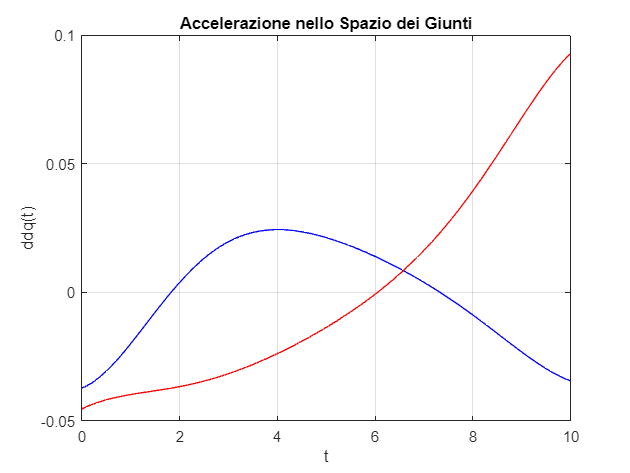


figure; plot(t,ddq1,'b',t,ddq2,'r');
grid on;
xlabel('t');
ylabel('ddq(t)');
title('Accelerazione nello Spazio dei Giunti');

## Percorso semicirconferenza 2)

### Legge Oraria e Generatore di riferimento

Le coordinate del centro sono $P_{\textrm{centro}} =\frac{P_2 -P_1 }{2}$

Parametrizzando l'equazione che descrive la traiettoria si ottiene $P\left(\theta \right)=\left\lbrack \begin{array}{c}
x_c \\
y_c 
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
R\;\cos \left(\theta \right)\\
R\;\sin \left(\theta \right)
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
x\left(\theta \right)\\
y\left(\theta \right)
\end{array}\right\rbrack \textrm{con}\;0\le \theta \le \pi$

$\theta =\theta \left(t\right)$ si può riscrivere l'equazione come $P\left(\theta \left(\sigma \right)\right)=P_{\textrm{centro}} +R$$\left\lbrack \begin{array}{c}
\cos \left(\theta \left(\sigma \right)\right)\\
\sin \left(\theta \left(\sigma \right)\right)
\end{array}\right\rbrack \;\textrm{con}\;\sigma =\frac{t-T_3 }{T_4 -T_3 }$


$$\theta \left(\sigma \right)=\theta_1 +\lambda \left(\sigma \right)\left(\theta_2 -\theta_1 \right)=\lambda \left(\sigma \right)\pi$$


Si rende necessario per ottenere un andamento realistico della posizione e della velocità usare una funzione $\lambda$del tipo $\lambda \left(\sigma \right)=-2\sigma^3 +3\sigma^2$

Sviluppando le equazioni si ottengono:

$P\left(t\right)=\left\lbrack \begin{array}{c}
x\left(t\right)\\
y\left(t\right)
\end{array}\right\rbrack$=$\left\lbrack \begin{array}{c}
\left.x_c +R\;\cos \left(\pi \left(-2{\left(\frac{t-T_3 }{T_4 -T_3 }\right)}^3 +3{\left(\frac{t-T_3 }{T_4 -T_3 }\right)}^2 \right.\right)\right)\\
\left.y_c +R\;\sin \left(\pi \left(-2{\left(\frac{t-T_3 }{T_4 -T_3 }\right)}^3 +3{\left(\frac{t-T_3 }{T_4 -T_3 }\right)}^2 \right.\right)\right)
\end{array}\right\rbrack$    da cui    $\dot{P\left(t\right)} \;=\left\lbrack \begin{array}{c}
\dot{x\left(t\right)} \\
\dot{y\left(t\right)} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
\left.-\frac{R\pi }{T_4 -T_3 }*\left(-6{\left(\frac{t-T_1 }{T_2 -T_1 }\right)}^2 +6\left(\frac{t-T_1 }{T_2 -T_1 }\right)\right)*\sin \left(\pi \left(-2{\left(\frac{t-T_3 }{T_4 -T_3 }\right)}^3 +3{\left(\frac{t-T_3 }{T_4 -T_3 }\right)}^2 \right.\right)\right)\\
\left.\frac{R\pi }{T_4 -T_3 }*\left(-6{\left(\frac{t-T_1 }{T_2 -T_1 }\right)}^2 +6\left(\frac{t-T_1 }{T_2 -T_1 }\right)\right)*\cos \left(\pi \left(-2{\left(\frac{t-T_3 }{T_4 -T_3 }\right)}^3 +3{\left(\frac{t-T_3 }{T_4 -T_3 }\right)}^2 \right.\right)\right)
\end{array}\right\rbrack$

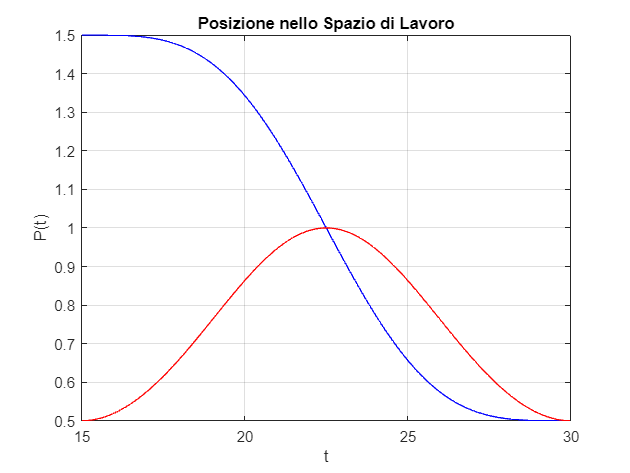

% Definizione del centro
Pc = [1, 0.5];

% Definizione del raggio
R = 0.5;

% Definizione dei tempi T3 e T4
T3 = 15;
T4 = 30;

% Generazione di valori di t da 15 a30
s_t = linspace(T3, T4, 150); % Esempio con 150 valori

%Generazione lambda e sigma
s_sigma= (s_t - T3) / (T4 - T3);

s_lambda=pi*(-2*s_sigma.^3+3*s_sigma.^2);

%% Calcoli delle funzioni spazio e velocità per ogni valore di t
% Inizializzazione dei vettori per i risultati
s_x = zeros(size(s_t)); s_y = zeros(size(s_t));
s_vx = zeros(size(s_t)); s_vy = zeros(size(s_t));
s_ax = zeros(size(s_t)); s_ay = zeros(size(s_t));
s_c2 = zeros(size(s_t)); s_s2 = zeros(size(s_t));
s_c1 = zeros(size(s_t)); s_s1 = zeros(size(s_t));
s_q2 = zeros(size(s_t)); s_q1 = zeros(size(s_t));
s_dq2 = zeros(size(s_t)); s_dq1 = zeros(size(s_t));
s_ddq2 = zeros(size(s_t)); s_ddq1 = zeros(size(s_t));

% Calcolo dei valori per ogni valore di t
for i = 1:numel(s_t)
    % Calcoli delle funzioni spazio
    s_x(i) = Pc(1) + R*cos(s_lambda(i));
    s_y(i) = Pc(2) + R*sin(s_lambda(i));

    s_P=[s_x(i);s_y(i)];

    % Calcoli delle funzioni velocità
    s_vx(i) = (-R*pi/ (T4 - T3)) * sin(s_lambda(i)) * ((-6*s_sigma(i)^2) +6*s_sigma(i));
    s_vy(i) = (R*pi/ (T4 - T3)) * cos(s_lambda(i)) * ((-6*s_sigma(i)^2) +6*s_sigma(i));

    % Calcolo accelerazione
    s_ax(i) = -R* ((pi/ (T4 - T3))^3) * sin(s_lambda(i)) * cos(s_lambda(i)) * (((-6*s_sigma(i)^2) +6*s_sigma(i))^2) * (-12*s_sigma(i)+6);
    s_ay(i) = -R* ((pi/ (T4 - T3))^3) * sin(s_lambda(i)) * cos(s_lambda(i)) * (((-6*s_sigma(i)^2) +6*s_sigma(i))^2) * (-12*s_sigma(i)+6);

    % Cinematica inversa
    % Calcolo di q2
    s_c2(i) = (s_x(i)^2 + s_y(i)^2 - L1^2 - L2^2) / (2 * L1 * L2);
    s_s2(i) = sqrt(1 - s_c2(i)^2);
    s_q2(i) = atan2(s_s2(i), s_c2(i));
    
    % Calcolo di q1
    A=[L1+L2*s_c2(i) -L2*s_s2(i); 
    L2*s_s2(i) (L1+L2*s_c2(i))];
    s_Q1=(inv(A))*s_P;
    s_c1(i)=s_Q1(1);
    s_s1(i)=s_Q1(2);
    s_q1(i)=atan2(s_s1(i),s_c1(i));
end

figure; plot(s_t,s_x,'b',s_t,s_y,'r');
grid on;
xlabel('t');
ylabel('P(t)');
title('Posizione nello Spazio di Lavoro');

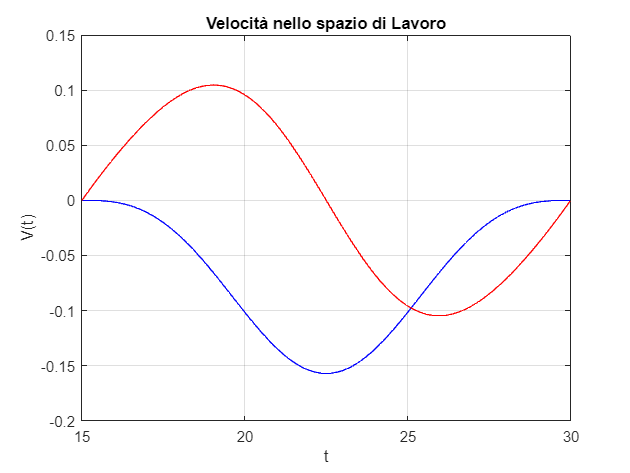


figure; plot(s_t,s_vx,'b',s_t,s_vy,'r'); 
grid on;
xlabel('t');
ylabel('V(t)');
title('Velocità nello spazio di Lavoro');

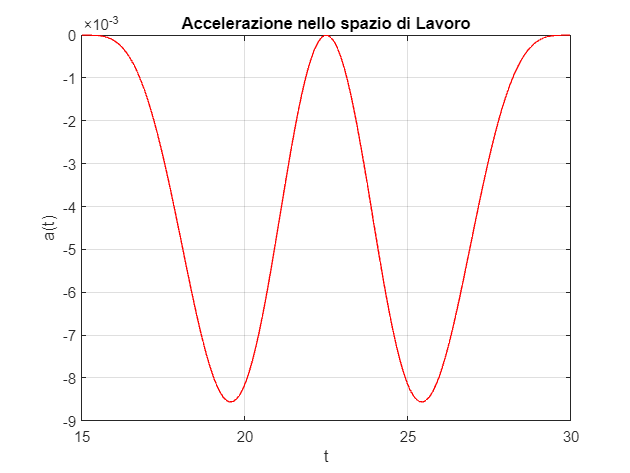


figure; plot(s_t,s_ax,'b',s_t,s_ay,'r');
grid on;
xlabel('t');
ylabel('a(t)');
title('Accelerazione nello spazio di Lavoro');

### Cinematica inversa

Il procedimento è analogo a quello illustrato nella sezione 1)


$$c_2 =\frac{P_x^2 +P_y^2 -L_1^2 -L_2^2 }{2L_1 L_2 }$$
        
$$s_2 =\pm \sqrt{1-{\left(c_2 \right)}^2 }$$
    
$$\to \;q_2 =\textrm{ATAN2}\left(s_2 ,c_2 \right)$$



$$Q_1 =A^{-1} P$$
    
$$\to q_1 =\textrm{ATAN2}\left(s_1 ,c_1 \right)$$


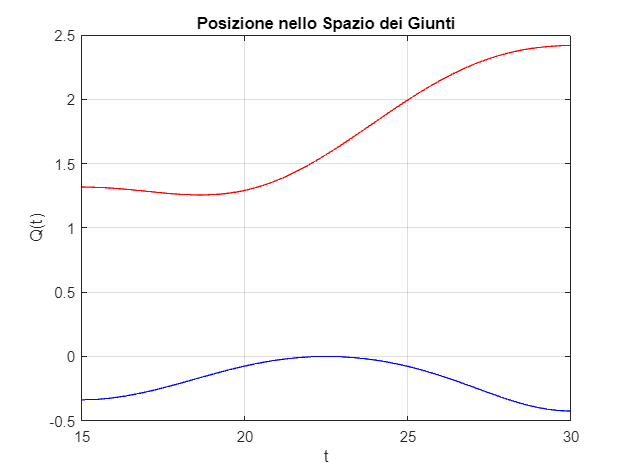

figure; plot(s_t,s_q1,'b',s_t,s_q2,'r');
grid on;
xlabel('t');
ylabel('Q(t)');
title('Posizione nello Spazio dei Giunti');

### Cinematica differenziale inversa

Il procedimento è analogo a quello illustrato nella sezione 1)

$\dot{P} =J\left(Q\right)\dot{Q}$    dove $J=\left\lbrack \begin{array}{cc}
-L_1 s_1 -L_2 s_{12}  & -L_2 s_{12} \\
L_1 c_1 +L_2 c_{12}  & L_2 c_{12} 
\end{array}\right\rbrack$ il cui determinante se diverso da zero permette di scrivere


$$\dot{Q} =J^{-1} \left(Q\right)\dot{P}$$


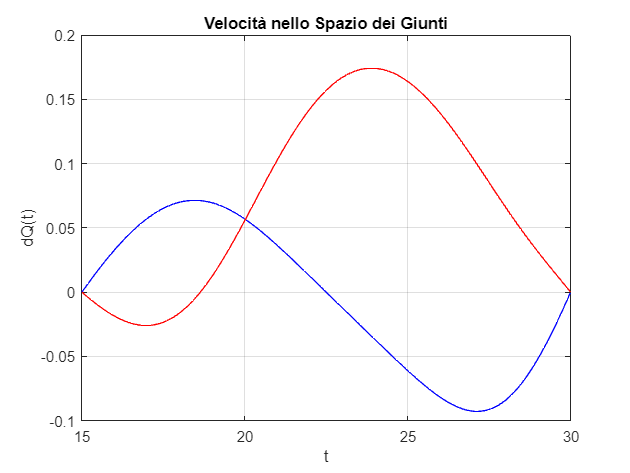

for i = 1:numel(s_t) 
% Calcolo della matrice J
    s_J = [-L1*sin(s_q1(i)) - L2*sin(s_q1(i)+s_q2(i)), -L2*sin(s_q1(i)+s_q2(i));
          L1*cos(s_q1(i)) + L2*cos(s_q1(i)+s_q2(i)), L2*cos(s_q1(i)+s_q2(i))];


    % Inversione della matrice J
    s_J_inv = inv(s_J);

    % Moltiplicazione della matrice invertita per il vettore di velocità
    s_dq = (s_J_inv) * [s_vx(i), s_vy(i)]';

    % Estrazione dei valori di dq1 e dq2
    s_dq1(i) = s_dq(1, :);
    s_dq2(i) = s_dq(2, :);

    % Accelerazione
    Jp = [-L1*s_c1(i)*s_dq1(i)-L2*cos(s_q1(i)+s_q2(i))*(s_dq1(i)+s_dq2(i)), -L2*cos(s_q1(i)+s_q2(i))*(s_dq1(i)+s_dq2(i));
        -L1*s_s1(i)*s_dq1(i)-L2*sin(s_q1(i)+s_q2(i))*(s_dq1(i)+s_dq2(i)), -L2*sin(s_q1(i)+s_q2(i))*(s_dq1(i)+s_dq2(i))];

    J = [-L1*s_s1(i)-L2*sin(s_q1(i)+s_q2(i)), -L2*sin(s_q1(i)+s_q2(i));
        L1*s_c1(i)+L2*cos(s_q1(i)+s_q2(i)), L2*cos(s_q1(i)+s_q2(i))];
    b = [s_ax(i);s_ay(i)] - Jp*[s_dq1(i);s_dq2(i)];
    Qpp = (inv(J))*b;

     s_ddq1(i) = Qpp(1, :);
    s_ddq2(i) = Qpp(2, :);

end

figure; 
plot(s_t,s_dq1,'b', s_t,s_dq2, 'r');
grid on;
xlabel('t');
ylabel('dQ(t)');
title('Velocità nello Spazio dei Giunti');

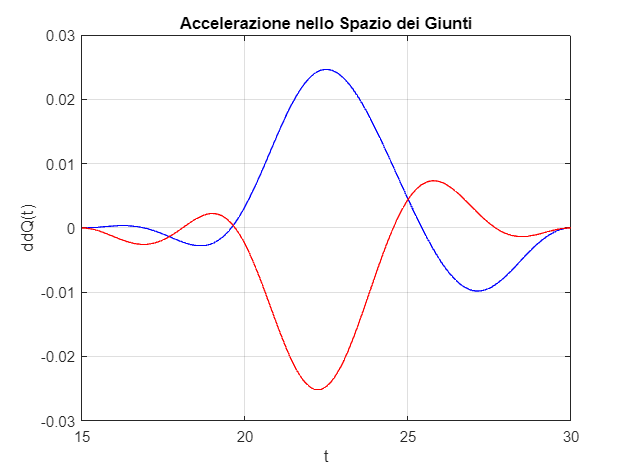


figure; 
plot(s_t,s_ddq1,'b', s_t,s_ddq2, 'r');
grid on;
xlabel('t');
ylabel('ddQ(t)');
title('Accelerazione nello Spazio dei Giunti');

### Vista d'insieme da T0 a T4

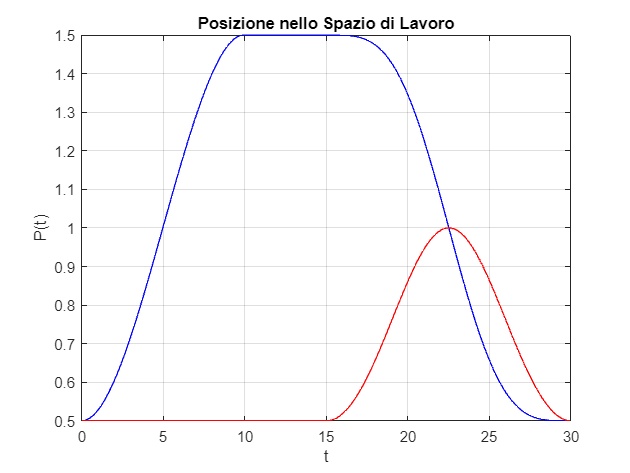

% Tempo totale
t_tot=linspace(T1, T4, 300);

x_tot = zeros(size(t_tot));
y_tot = zeros(size(t_tot));

vx_tot = zeros(size(t_tot));
vy_tot = zeros(size(t_tot));

ax_tot = zeros(size(t_tot));
ay_tot = zeros(size(t_tot));

q1_tot = zeros(size(t_tot));
q2_tot = zeros(size(t_tot));

dq1_tot = zeros(size(t_tot));
dq2_tot = zeros(size(t_tot));

ddq1_tot= zeros(size(t_tot)); 
ddq2_tot= zeros(size(t_tot)); 

for i=1:100
    x_tot(i) = x(i);    y_tot(i) = y(i);
    vx_tot(i) = vx(i);    vy_tot(i) = vy(i);
    ax_tot(i) = ax(i);    ay_tot(i) = ay(i);
    q1_tot(i) = q1(i);    q2_tot(i) = q2(i);
    dq1_tot(i) = dq1(i);    dq2_tot(i) = dq2(i);
    ddq1_tot(i) = ddq1(i);    ddq2_tot(i) = ddq2(i);
end
for i=1:50
    x_tot(i+100) = x(100);    y_tot(i+100) = y(100);
    vx_tot(i+100) = vx(100);    vy_tot(i+100) = vy(100);
    ax_tot(i+100) = ax(100);    ay_tot(i+100) = ay(100);
    q1_tot(i+100) = q1(100);    q2_tot(i+100) = q2(100);
    dq1_tot(i+100) = dq1(100);    dq2_tot(i+100) = dq2(100);
    ddq1_tot(i+100) = ddq1(100);    ddq2_tot(i+100) = ddq2(100);
end
for i=1:150
    x_tot(i+150) = s_x(i);    y_tot(i+150) = s_y(i);
    vx_tot(i+150) = s_vx(i);    vy_tot(i+150) = s_vy(i);
    ax_tot(i+150) = s_ax(i);    ay_tot(i+150) = s_ay(i);
    q1_tot(i+150) = s_q1(i);    q2_tot(i+150) = s_q2(i);
    dq1_tot(i+150) = s_dq1(i);    dq2_tot(i+150) = s_dq2(i);
    ddq1_tot(i+150) = s_ddq1(i);    ddq2_tot(i+150) = s_ddq2(i);
end

figure; plot(t_tot,x_tot,'b',t_tot,y_tot,'r');
grid on;
xlabel('t');
ylabel('P(t)');
title('Posizione nello Spazio di Lavoro');

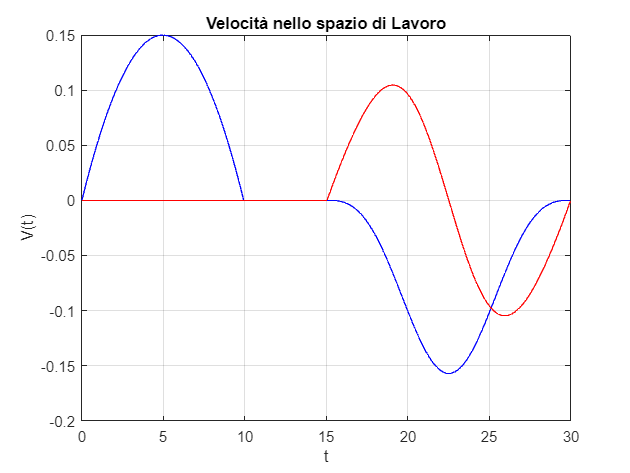


figure; plot(t_tot,vx_tot,'b',t_tot,vy_tot,'r'); 
grid on;
xlabel('t');
ylabel('V(t)');
title('Velocità nello spazio di Lavoro');

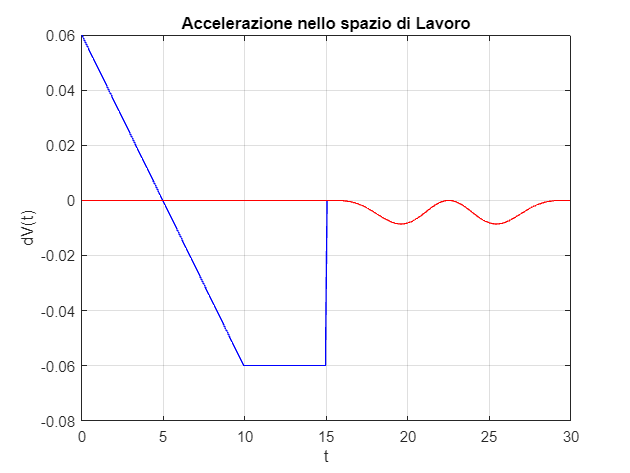

figure; plot(t_tot,ax_tot,'b',t_tot,ay_tot,'r'); 
grid on;
xlabel('t');
ylabel('dV(t)');
title('Accelerazione nello spazio di Lavoro');

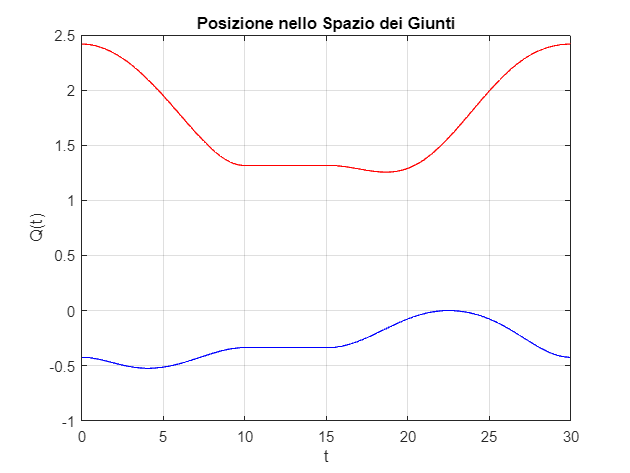


figure; plot(t_tot,q1_tot,'b',t_tot,q2_tot,'r');
grid on;
xlabel('t');
ylabel('Q(t)');
title('Posizione nello Spazio dei Giunti');

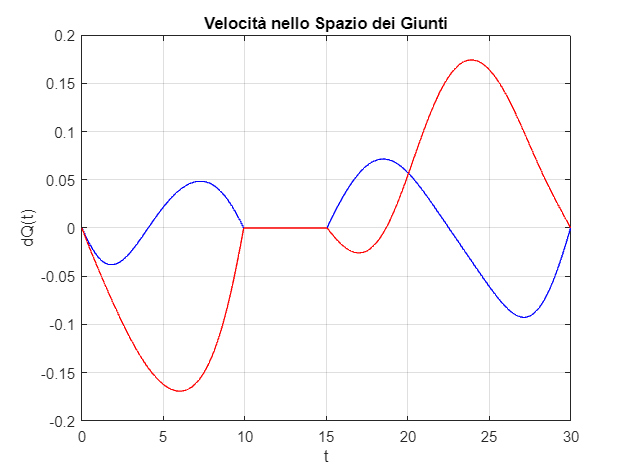


figure; plot(t_tot,dq1_tot,'b',t_tot,dq2_tot,'r');
grid on;
xlabel('t');
ylabel('dQ(t)');
title('Velocità nello Spazio dei Giunti');

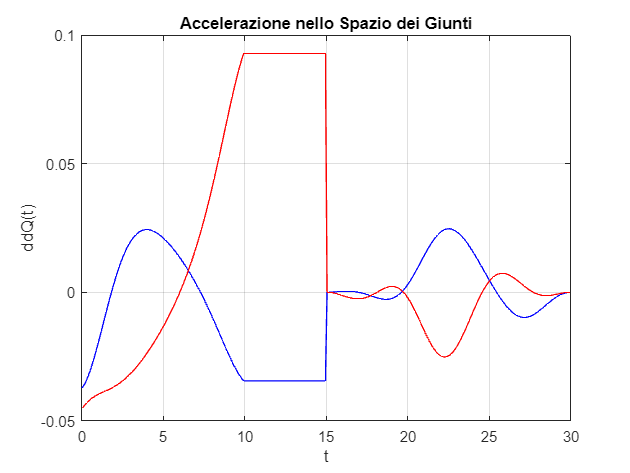


figure; plot(t_tot,ddq1_tot,'b',t_tot,ddq2_tot,'r');
grid on;
xlabel('t');
ylabel('ddQ(t)');
title('Accelerazione nello Spazio dei Giunti');


P=[x_tot;y_tot];
V=[vx_tot;vy_tot];
Q=[q1_tot;q2_tot];
dQ=[dq1_tot,dq2_tot];

## Dinamica

### Approccio Lagrangiano

Considerando la geometria del robot risultano i seguenti vettori

$Q=\left\lbrack \begin{array}{c}
q_1 \\
q_2 
\end{array}\right\rbrack$vettore delle variabili di giunto.

$p_{\textrm{c1}} =\left\lbrack \begin{array}{c}
l_1 c_1 \\
l_1 s_1 
\end{array}\right\rbrack \;$$p_{\textrm{c2}} =\left\lbrack \begin{array}{c}
a_1 c_1 +l_2 c_{12} \\
a_1 s_1 +l_2 s_{12} 
\end{array}\right\rbrack \;$ baricentri dei due bracci

$v_{\textrm{c1}} =\left\lbrack \begin{array}{c}
{-\dot{q_1 \;} l}_1 s_1 \\
\dot{q_1 } l_2 c_2 
\end{array}\right\rbrack \;$$v_{\textrm{c2}} =\left\lbrack \begin{array}{c}
{-\dot{q_1 } \;a}_1 s_1 -\left(\dot{q_1 } +\dot{q_2 } \right)l_2 s_{12} \\
{\dot{q_1 } \;a}_1 c_1 +\left(\dot{q_1 } +\dot{q_2 } \right)l_2 c_{12} 
\end{array}\right\rbrack \;$velocità rispetto ai baricentri

$g=\left\lbrack \begin{array}{c}
0\\
-g
\end{array}\right\rbrack \;$accelerazione di gravità

Dove $l_1 \;\textrm{ed}\;l_2$ sono le distanze dei due baricentri, ovvero $l_1 =\frac{a_1 }{2}$ ec $l_2 =\frac{a_2 }{2}$

Per calcolare l’energia cinetica bisogna introdurre i momenti di inerzia delle due aste rispetto ad assi passanti per i rispettivi baricentri

$I_1 =\frac{1}{12}m_1 a_1^2$ ed $I_2 =\frac{1}{12}m_2 a_2^2$

Da questi dati è possibile ricavare l'energia cinetica e l'energia potenziale


$${\textrm{Ec}}_1 =\frac{1}{2}m_1 \;{\left(p_{\textrm{c1}} \right)}^T p_{\textrm{c1}} +\frac{1}{2}I_1 \omega^2 =\frac{1}{2}m_1 l_1^2 \dot{{\left(q_1 \right)}^2 } +\frac{1}{2}I_1 \dot{{\left(q_1 \right)}^2 }$$



$${\textrm{Ec}}_2 =\frac{1}{2}m_2 \;{\left(p_{\textrm{c2}} \right)}^T p_{\textrm{c2}} +\frac{1}{2}I_2 \omega^2 =\;\frac{1}{2}m_2 \left\lbrack {\dot{\left(q_1 \right)} }^2 a_1^2 +{\left(\dot{q_1 } +\dot{q_2 } \right)}^2 l_2^2 +2\dot{q_1 } \left(\dot{q_1 } +\dot{q_2 } \right)a_1 l_2 c_2 \right\rbrack +\frac{1}{2}I_{21} {\left(\dot{q_1 } +\dot{q_2 } \right)}^2$$



$$\textrm{Ec}={\textrm{Ec}}_1 +{\textrm{Ec}}_2 =$$

$$\frac{1}{2}m_1 l_1^2 \dot{{\left(q_1 \right)}^2 } +\frac{1}{2}I_1 \dot{{\left(q_1 \right)}^2 } +\frac{1}{2}m_2 \left\lbrack {\dot{\left(q_1 \right)} }^2 a_1^2 +{\left(\dot{q_1 } +\dot{q_2 } \right)}^2 l_2^2 +2\dot{q_1 } \left(\dot{q_1 } +\dot{q_2 } \right)a_1 l_2 c_2 \right\rbrack +\frac{1}{2}I_{21} {\left(\dot{q_1 } +\dot{q_2 } \right)}^2$$


Per quanto riguarda invece l’energia potenziale gravitazionale


$$\textrm{Ep}=-{\;m}_1 g^T p_{\textrm{c1}} \;-\;m_2 g^T p_{\textrm{c2}} \;=m_1 \;g\;l_1 \;s_1 +m_2 \;g\;\left(a_1 s_1 +l_2 s_{12} \right)$$


Si può dunque definire la funzione Lagrangiana


$$L=\textrm{Ec}-\textrm{Ep}$$


Da cui è possibile ricavare la coppia


$$\frac{d}{\textrm{dt}}\;\frac{\partial L}{\partial \dot{Q} }-\frac{\partial L}{\partial Q}=T$$


Prima equazione


$$\begin{array}{l}
T_1 =\frac{d}{\textrm{dt}}\;\frac{\partial L}{\partial \dot{q_1 } }-\frac{\partial L}{\partial q_1 }=\\
\;\;\;\;\;=\left(m_1 l_1^2 +I_1 +m_2 a_1^2 +m_2 l_2^2 +2m_2 a_1 l_2 c_2 +I_2 \right)\ddot{q_1 } +\left(m_2 l_2^2 +m_2 a_1 l_2 c_2 +I_2 \right)\ddot{q_2 } +\\
\;\;\;\;\;\;\;\;\;\;\;-2m_2 a_1 l_2 s_2 \dot{{\;q}_1 } \dot{\;q_2 } -m_2 a_1 l_2 s_2 {\dot{{\;q}_2 } }^2 +m_1 l_1 {\;g\;c}_1 +m_2 \;g\;a_1 c_1 +m_2 \;g\;l_2 {\;c}_{12} 
\end{array}$$


Seconda equazione


$$\begin{array}{l}
T_2 =\frac{d}{\textrm{dt}}\;\frac{\partial L}{\partial \dot{q_2 } }-\frac{\partial L}{\partial q_2 }=\\
\;\;\;\;\;=\left(m_2 l_1^2 +m_2 a_1 l_2 c_2 +I_2 \right)\ddot{q_1 } +\left(m_2 l_2^2 +I_2 \right)\ddot{q_2 } +\\
\;\;\;\;\;\;\;\;\;\;\;+m_2 a_1 l_2 s_2 {\dot{{\;q}_1 } }^2 +m_2 \;g\;l_2 {\;c}_{12} 
\end{array}$$


Che in forma vettoriale si scrivono


$$\left\lbrack \begin{array}{cc}
m_1 l_1^2 +I_1 +m_2 a_1^2 +m_2 l_2^2 +2m_2 a_1 l_2 c_2 +I_2  & m_2 l_2^2 +m_2 a_1 l_2 c_2 +I_2 \\
m_2 l_1^2 +m_2 a_1 l_2 c_2 +I_2  & m_2 l_2^2 +I_2 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\ddot{q_1 } \\
\ddot{q_2 } 
\end{array}\right\rbrack +\left\lbrack \begin{array}{cc}
-2m_2 a_1 l_2 s_2 \dot{\;q_2 }  & -m_2 a_1 l_2 s_2 \dot{{\;q}_2 } \\
m_2 a_1 l_2 s_2 \dot{{\;q}_1 }  & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\dot{{\;q}_1 } \\
\dot{{\;q}_2 } 
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
\left(m_1 l_1 +m_2 a_1 \right)g\;c_1 +m_2 \;g\;l_2 \;c_{12} \\
m_2 \;g\;l_2 {\;c}_{12} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
T_1 \\
T_2 
\end{array}\right\rbrack$$


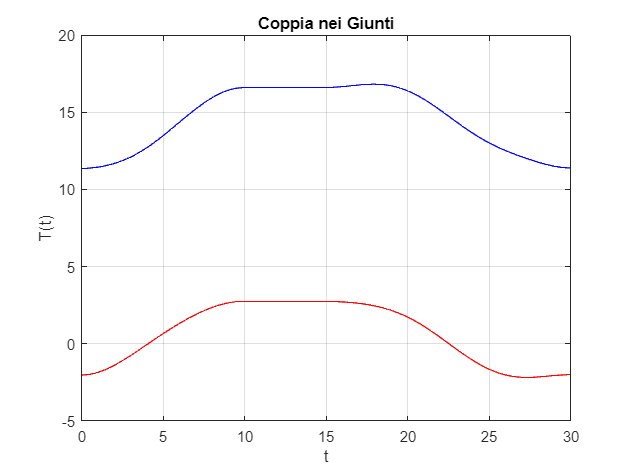

% Massa dei bracci
m1=1; m2=1;

% Lunghezza dei bracci
a1=1; a2=1;

% Distanza baricentro
l1=a1/2; l2=a2/2;

% Accelerazione di gravità
g=9.81;

%Momenti di Inerzia
I1=(1/12)*m1*a1^2;
I2=(1/12)*m2*a2^2;

% Coppie

T1= zeros(size(t_tot));
T2= zeros(size(t_tot));

for i = 1:numel(t_tot)

    % Matrice di Inerzia
    M=[(m1*l1^2 +I1+m2*a1^2+m2*l2^2 +2*m2*a1*l2*cos(q2_tot(i))+I2), (m2*l2^2 + m2*a1*l2*cos(q2_tot(i))+I2);
          (m2*l1^2 +m2*a1*l2*cos(q2_tot(i))+I2), (m2*l2^2 +I2)];
    % Matrice delle Forze Apparenti
    H=[-2*m2*a1*l2*sin(q2_tot(i))*dq2_tot(i), -m2*a1*l2*sin(q2_tot(i))*dq2_tot(i);
          m2*a1*l2*sin(q2_tot(i))*dq1_tot(i), 0];
    
    % Termini Gravitazionali
    G=[(m1*l1+m2*a1)*g*cos(q1_tot(i))+m2*g*l2*cos(q1_tot(i)+q2_tot(i)); m2*g*l2*cos(q1_tot(i)+q2_tot(i))];

    % Calcolo delle Coppie
    T=M*[ddq1_tot(i);ddq2_tot(i)]+H*[dq1_tot(i);dq2_tot(i)]+G;

    T1(i) = T(1, :);
    T2(i) = T(2, :);
end

figure; plot(t_tot,T1,'b',t_tot,T2,'r');
grid on;
xlabel('t');
ylabel('T(t)');
title('Coppia nei Giunti');

L'equazione del modello dinamico si può dunque scrivere come


$$M\left(Q\right)\ddot{Q} +H\left(Q,\dot{Q} \right)\dot{Q} +G\left(Q\right)=T$$


che prendendo in considerazione l'attrito nei giunti diventa


$$M\left(Q\right)\ddot{Q} +H\left(Q,\dot{Q} \right)\dot{Q} +B\dot{Q} +G\left(Q\right)=T$$


In un modello a ciclo aperto la coppia generata attraverso queste equazioni viene poi adoperata nel modello reale del robot per generare i valori reali delle variabili di giunto.

In un modello in retroazione la coppia ai giunti viene invece generata attraverso l'equazione


$$T=K_p *e_p +K_v *e_v$$
 

dove $e_p \;$e $e_v$ sono gli errori rispettivamente di posizione e velocità dei giunti, ovvero $\left.{\left(Q\right.}_r -Q\right)$ e $\left(\dot{Q_r } -\dot{Q} \right)$

mentre $K_p$ e $K_v$ sono delle matrici che rappresentano i guadagni, entrambe definite positive e diagonali.

Sostituendo l'equazione della coppia in retroazione con il modello reale del robot (che coincide per semplificazione con il modello dinamico ideale) si ottiene


$$\left.M\left(Q\right)\ddot{Q} +H\left(Q,\dot{Q} \right)\dot{Q} +B\dot{Q} +G\left(Q\right)=K_p {\left(Q\right.}_r -Q\right)+K_v \left(\dot{Q_r } -\dot{Q} \right)$$



$$M\left(Q\right)\ddot{Q} +\left\lbrack H\left(Q,\dot{Q} \right)+B+K_v \right\rbrack \dot{Q} +G\left(Q\right)+K_p Q=K_p Q_r +K_v \dot{Q_r }$$


## Dinamica inversa

Avendo a disposizione il modello del robot e quindi il suo comportamento è possibile determinare l'accelerazione dei giunti poiché la matrice di inerzia $M\left(Q\right)\;$è sempre invertibile in quanto definita positiva

Si può perciò scrivere


$$\ddot{Q} ={-M}^{-1} \left\lbrack H\left(Q,\dot{Q} \right)+B\right\rbrack \dot{Q} -M^{-1} G\left(Q\right)+M^{-1} T$$


Che dopo integrazione permette di ottenere i valori di Velocità e Posizione dei giunti $\dot{Q} \;e\;Q$, necessari per calcolare l'errore nel modello a ciclo chiuso

## Leggi di controllo più precise

Ipotizzando leggi di controllo più precise è possibile ridurre gli effetti di interferenza delle forze apparenti, dell'attrito o della gravità

Ad esempio ipotizzando una legge di controllo


$${T_1 \;=\;K}_p \left(Q_r -Q\right)+K_v \left(\dot{Q_r } -\dot{Q} \right)+G_n \left(Q\right)$$
 

dove $G_n \left(Q\right)$ è un termine gravità nominale, sostituendo l'equazione della coppia nell'equazione del modello dinamico è possibile ridurre l'effetto della gravità, in quanto rimane solo l'effetto di un $\Delta G$.

Con una legge del tipo


$$T_2 =T_1 +$$

$$H_n \left(Q,\dot{Q} \right)\dot{Q}$$


è invece possibile ridurre l'effetto delle forze apparenti.

(Questa è la legge di controllo usata nel modello semplificato)

Sfruttando questo metodo ricorsivamente, ove possibile in quanto la stima di tali parametri è molto complessa, è possibile arrivare anche ad annullare l'effetto della matrice di inerzia, approssimando così il modello ad un sistema lineare


$$\ddot{q_i } \left(t\right)={\textrm{kv}}_i \;\dot{q_i } +{\textrm{kp}}_i \;q_i ={\textrm{kv}}_i \;\dot{{\textrm{qr}}_i } +{\textrm{kp}}_i \;{\textrm{qr}}_i$$


a cui è possibile applicare la trasformata di Laplace, ottenendo così una FdT del tipo


$$Q_i \left(s\right)=\frac{{\textrm{kp}}_i +{\textrm{kv}}_i \;s}{s^2 +{\textrm{kv}}_i \;s+{\textrm{kp}}_i }{\textrm{qr}}_i$$
 

## Schema Simulink

Q1r=transpose([t_tot; q1_tot]);
Q2r=transpose([t_tot; q2_tot]);
dQ1r=transpose([t_tot;dq1_tot]);
dQ2r=transpose([t_tot;dq2_tot]);

Kp=300;
Kv=80;
Ki=2;

%open_system("DinamicaElaborato_final.slx");

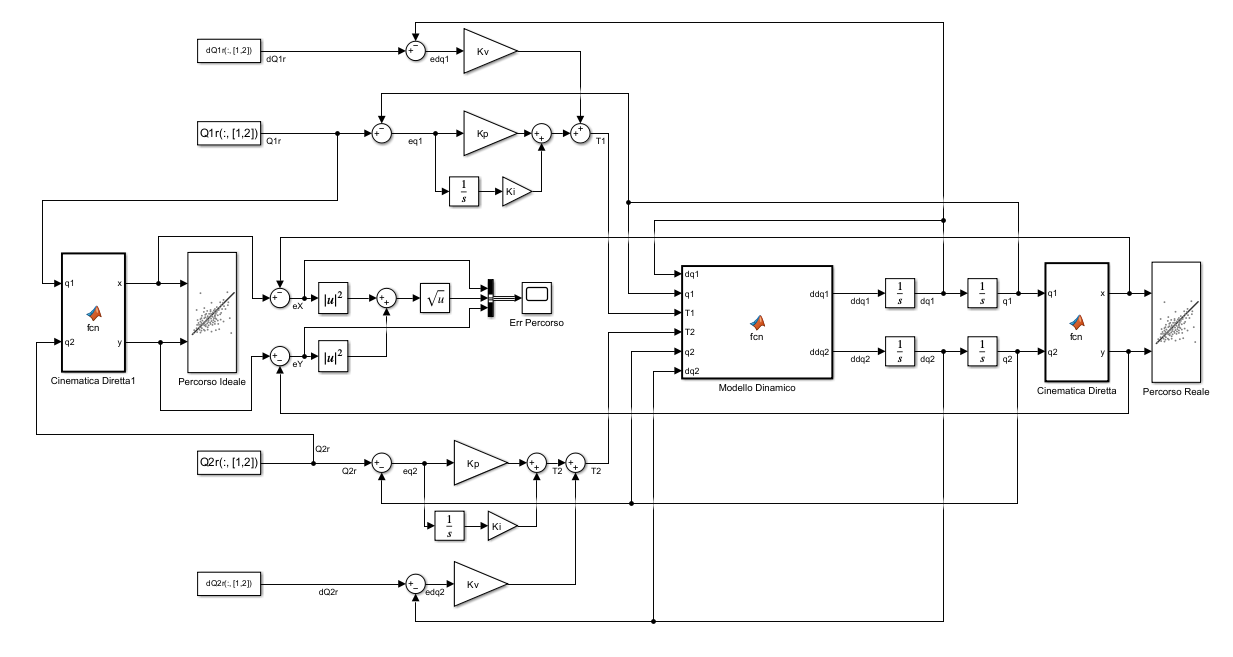

Questo schema Simulink rappresenta il sistema di controllo per il robot a due bracci.

Nel file di simulazione sono presenti due schemi:

- Il primo adotta una legge di controllo meno precisa (Modello Dinamico)

- Il secondo adotta una legge di controllo più precisa che elimina l'effetto delle forze apparenti e riduce l'effetto della gravità (Modello Dinamico Semplificato)

Descrizione dei blocchi principali e del loro ruolo nel sistema:

**Percorso Ideale e Percorso Reale**:

- **Percorso Ideale**: Rappresenta la traiettoria desiderata del robot.

- **Percorso Reale**: Mostra la traiettoria effettiva seguita dal robot.

**Cinematica Diretta**:

- Calcola le posizioni $x$ e $y$ dei giunti $q_1$ e $q_2$ del robot.

 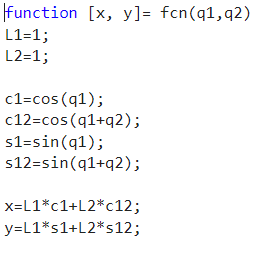

**Controllo di errore (Err Percorso)**:

- Confronta le posizioni attuali $x$ e $y$ con quelle desiderate.

- Calcola l'errore di posizione totale.

**Modulo Dinamico (M.D.Semplificato)**:

- Simula la dinamica del robot considerando le velocità ${\textrm{dq}}_1$ e ${\textrm{dq}}_2$, e le posizioni $q_1$ e $q_2$.

- Calcola le nuove accelerazioni ${\textrm{ddq}}_1$ e ${\textrm{ddq}}_2$ basate sulle coppie $T_1$ e $T_2$.

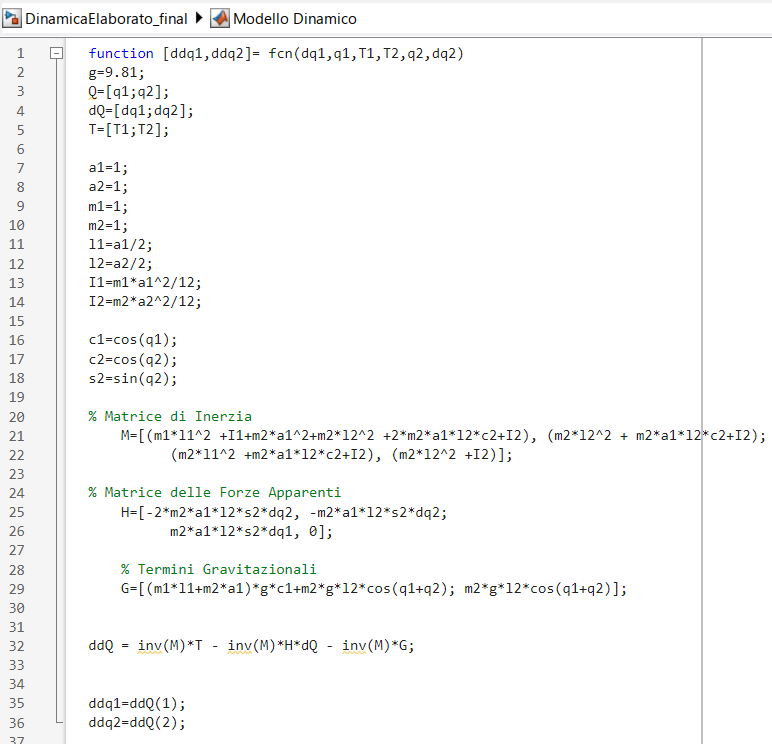 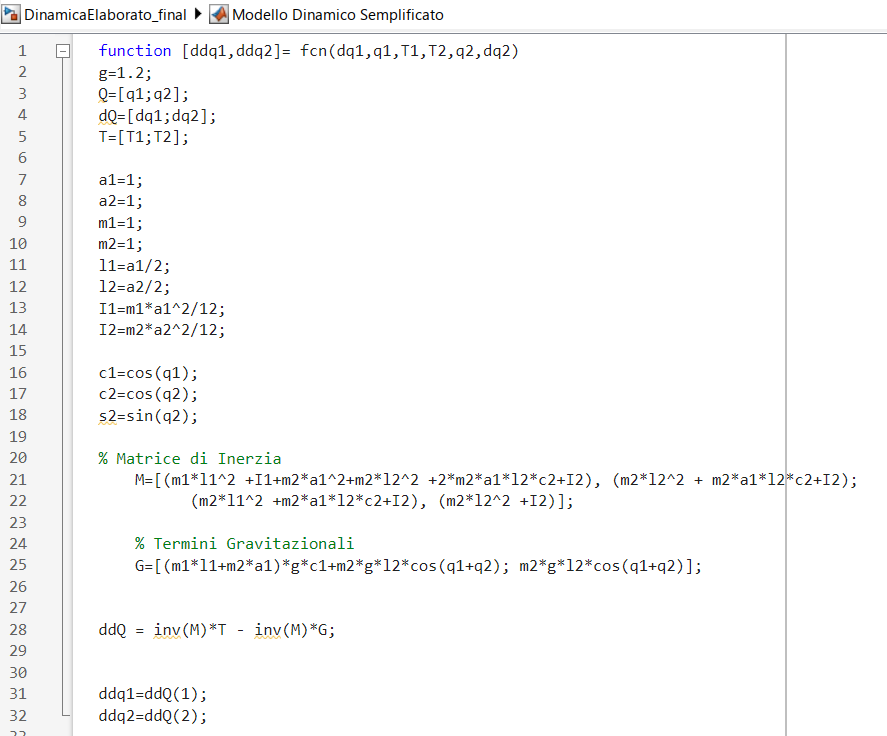

**Controllori PID (Proporzionale-Integrale-Derivativo)**:

- Ogni asse ha un controllore PID per correggere l'errore di posizione.

- I blocchi con $\textrm{Kp}$, $\textrm{Ki}$, e $\textrm{Kv}$ rappresentano rispettivamente i guadagni proporzionale, integrale e derivativo.

**Ingresso di riferimento**:

- $Q_{1r}$ e $Q_{2r}$ rappresentano i segnali di riferimento per le posizioni dei giunti.

- ${\textrm{dQ}}_{1r}$ e ${\textrm{dQ}}_{2r}$ rappresentano le velocità di riferimento.

**Feedback di posizione e velocità**:

- I segnali di velocità e posizione reali vengono retroazionati ai controllori PID per confrontarli con i valori di riferimento e correggere eventuali errori.

In sintesi, questo schema simula un sistema di controllo per un robot a due giunti, confrontando la posizione attuale con quella desiderata, calcolando l'errore, e applicando le correzioni necessarie tramite controllori PID per far seguire al robot il percorso ideale.

## Report Simulazione

Attraverso questi parametri PID si ottengono i seguenti grafici.

Kp=300;

Kv=80;

Ki=2;

#### Percorso Ideale

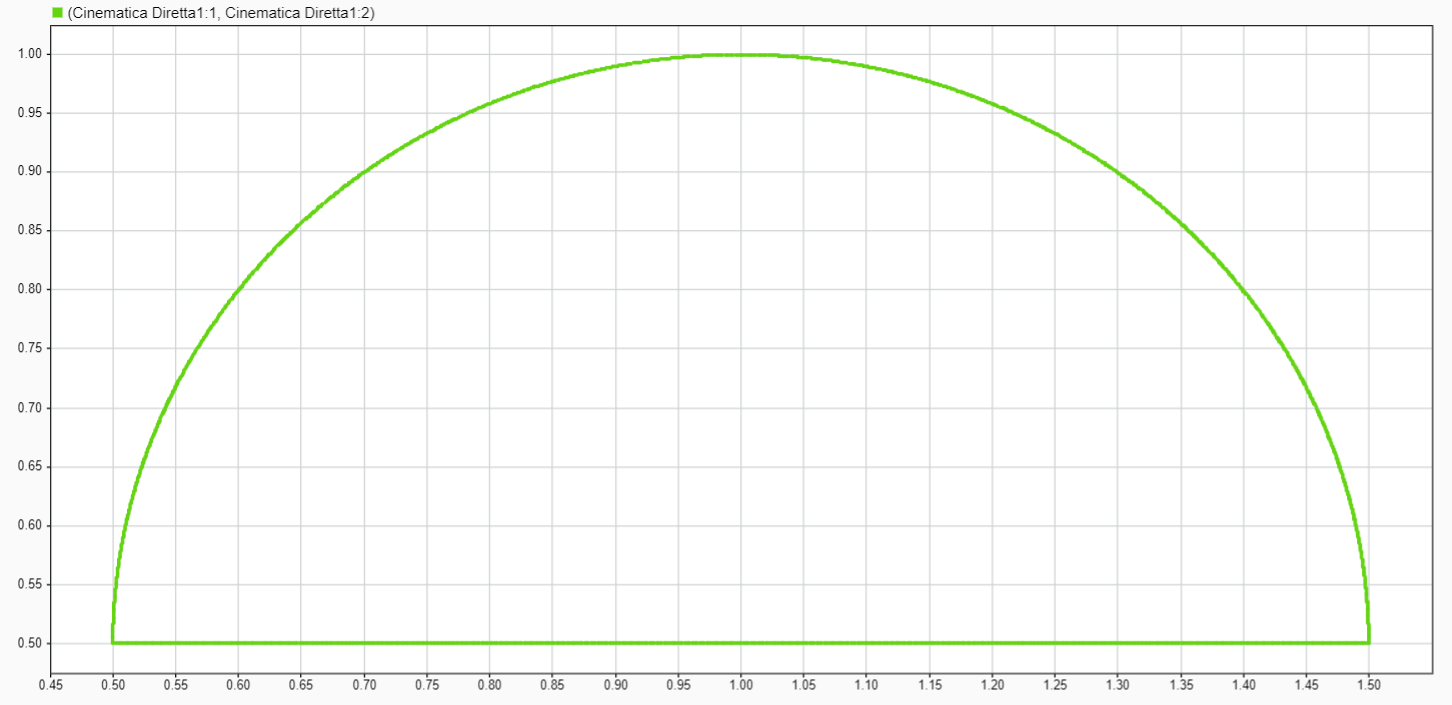

#### Percorso Reale Modello Dinamico (M.D.Semplificato)

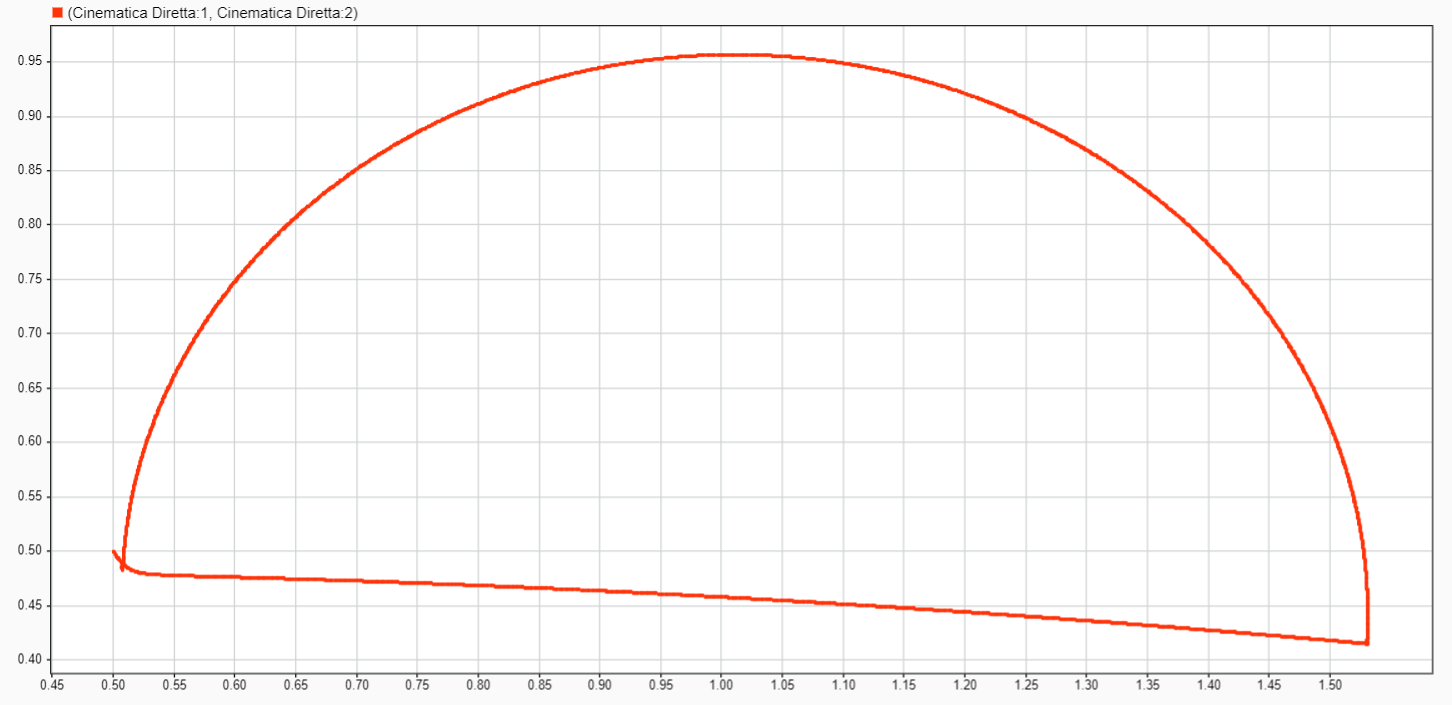 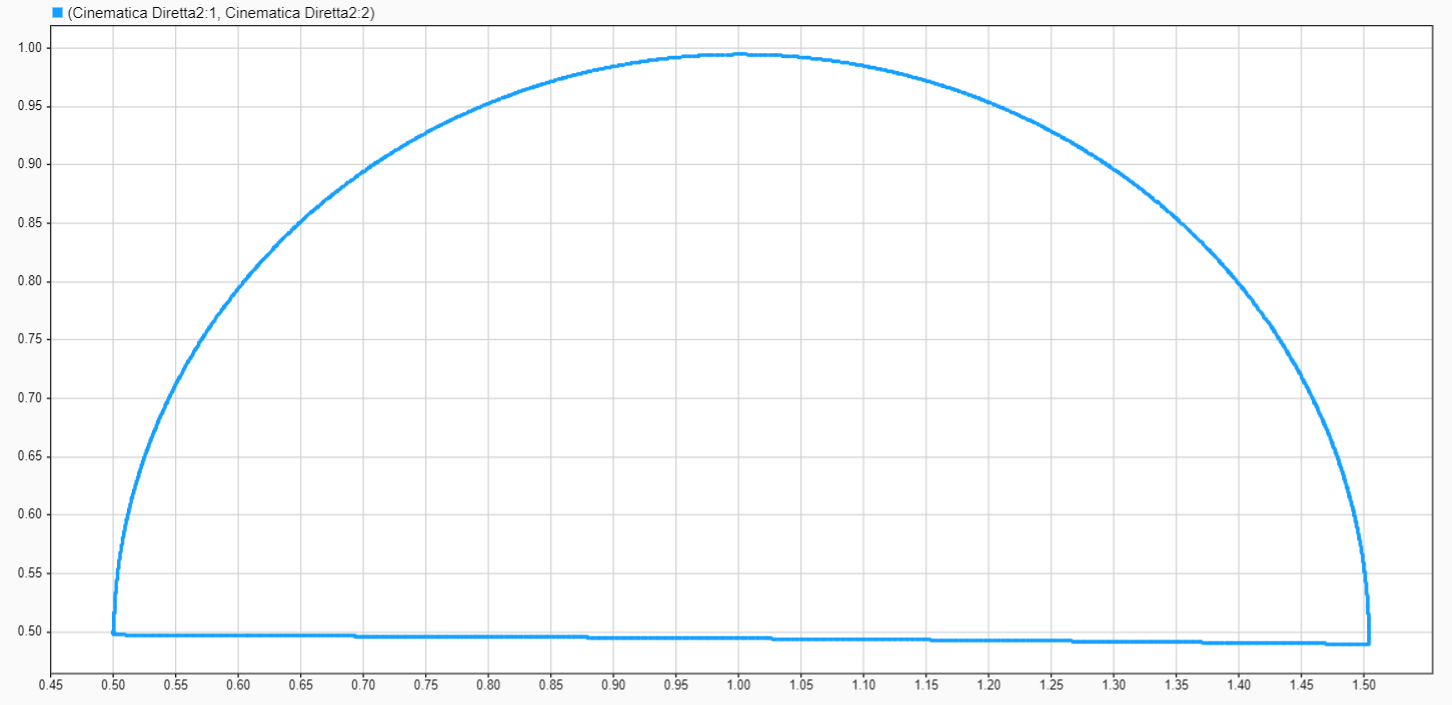

#### Errore di Posizione

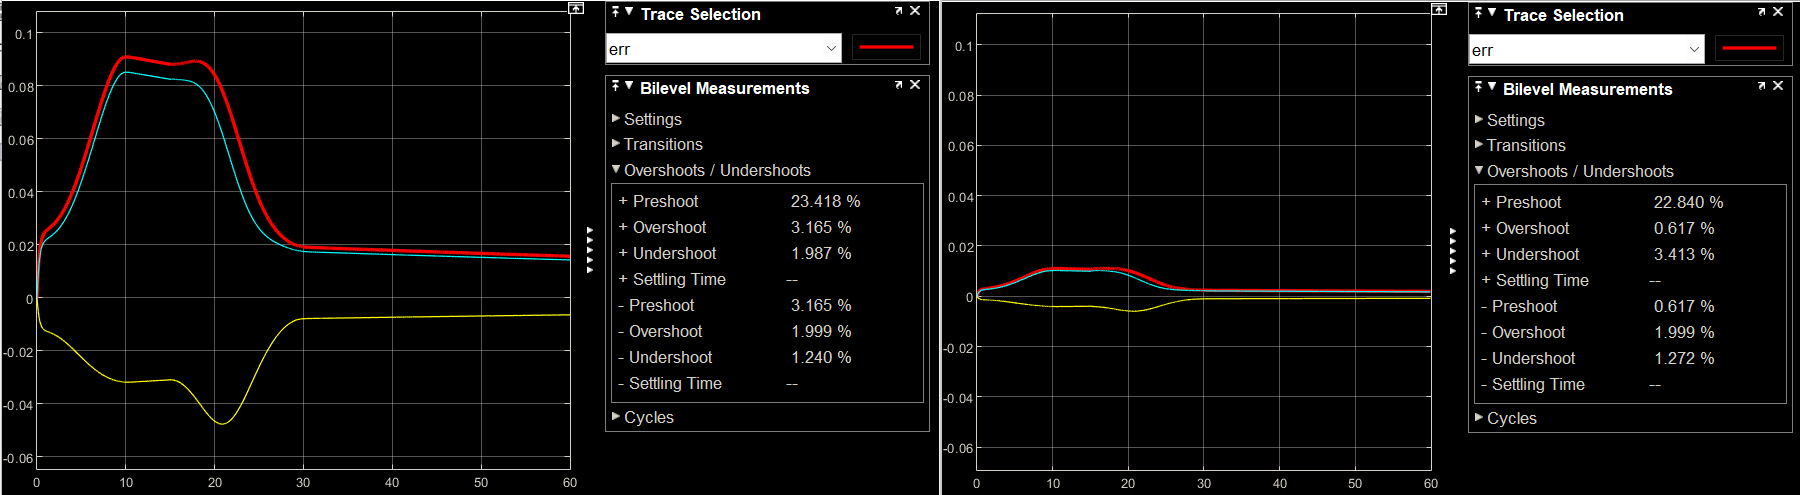

Come evidenziato dai grafici con questi parametri PID: 

- sarebbe necessaria un'ulteriore taratura per il modello dinamico standard, in quanto l'effetto della gravità è molto più evidente, e ciò va a  sfalsare di molto il percorso dell'attuatore rispetto al percorso ideale.

- sono accettabili per il modello dinamico semplificato, in quanto l'errore di posizione è molto meno significativo.

# Varianti

## Rototraslazione del Percorso

Per generare un nuovo percorso che sia uguale al precedente ma ruotato di $90\degree$ intorno all'asse $z$ e traslato dirispetto al vettore $\left\lbrack \begin{array}{c}
1\\
1\\
0
\end{array}\right\rbrack$ è necessario utilizzare una matrice di rototraslazione così composta:


$$\left\lbrack \begin{array}{cccc}
\cos \left(\theta \right) & -\sin \left(\theta \right) & 0 & 1\\
\sin \left(\theta \right) & \cos \left(\theta \right) & 0 & 1\\
0 & 0 & 1 & 0\\
0 & 0 & 0 & 1
\end{array}\right\rbrack$$


Moltiplicando il vettore posizione normalizzato per la matrice si ottiene il vettore poszione del nuovo percorso.


$$\left\lbrack \begin{array}{cccc}
\cos \left(\theta \right) & -\sin \left(\theta \right) & 0 & 1\\
\sin \left(\theta \right) & \cos \left(\theta \right) & 0 & 1\\
0 & 0 & 1 & 0\\
0 & 0 & 0 & 1
\end{array}\right\rbrack \;\left\lbrack \begin{array}{c}
x\\
y\\
z\\
1
\end{array}\right\rbrack \;=\left\lbrack \begin{array}{c}
\hat{x} \\
\hat{y} \\
\hat{z} \\
1
\end{array}\right\rbrack$$


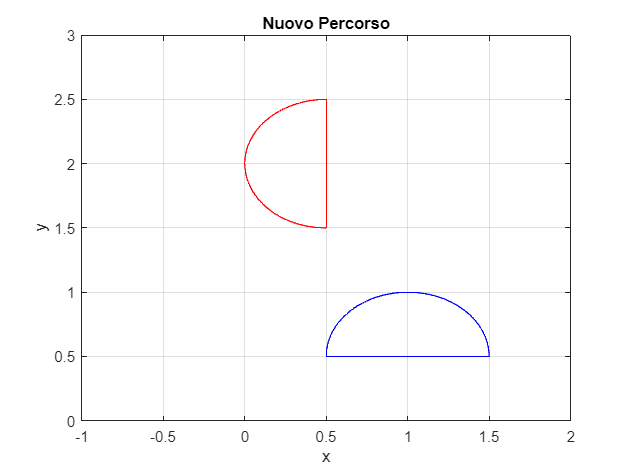

x_NewP = zeros(size(t_tot));
y_NewP = zeros(size(t_tot));

% Definire l'angolo di rotazione (in radianti)
Theta = pi/2;

% Calcolare la matrice di rototraslazione RT direttamente
RT = [cos(Theta), -sin(Theta), 0, 1;
      sin(Theta), cos(Theta), 0, 1;
      0, 0, 1, 0;
      0, 0, 0, 1];

for i=1:300
    POld=[x_tot(i);y_tot(i);0;1];
    PNew = RT * POld;
    x_NewP(i) = PNew(1);
    y_NewP(i) = PNew(2);
end
figure; 
plot(x_NewP,y_NewP,'r');
hold on;
plot(x_tot,y_tot, 'b');
axis([-1 2 0 3]);
grid on;
xlabel('x');
ylabel('y');
title('Nuovo Percorso');

## Aggiunta del Motore

Nella realtà la generazione delle coppie che agiscono sui giunti, rotoidali o prismatici, avviene attraverso dei Motori, generalmente elettrici D.C., ma che possono anche essere A.C. oppure motori idraulici o pneumatici.

In un motore elettrico l'elettricità in ingresso, corrente e differenza di potenziale, vengono convertiti in energia meccanica come movimento rotativo. 

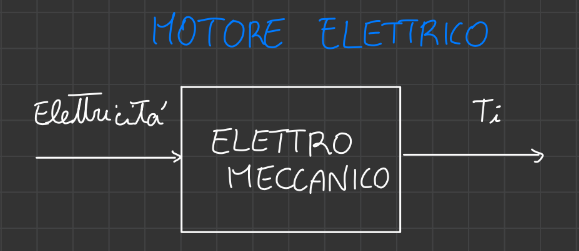 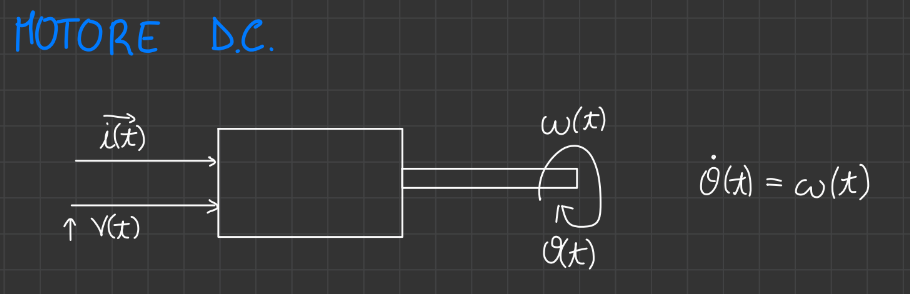

La coppia generata è proporzionale alla corrente $T_i \proptoi_i$

La velocità di rotazione $\omega$ è "quasi proporzionale" alla differenza di potenziale $V$.

Al motore è spesso collegato uno o più riduttori di giri che permettono di aumentare la coppia finale erogata a parità di rotazione dell'asse primario. Conoscendo tale velocità di rotazione ed i rapporti di riduzione è possibile calcolare con precisione assoluta anche la velocità di rotazione e la coppia dell'asse finale.

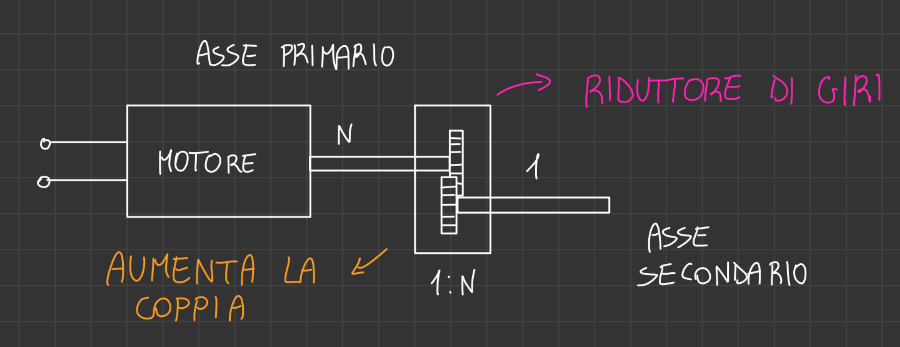

Il modello elettrico del motore può essere rappresentato come segue:

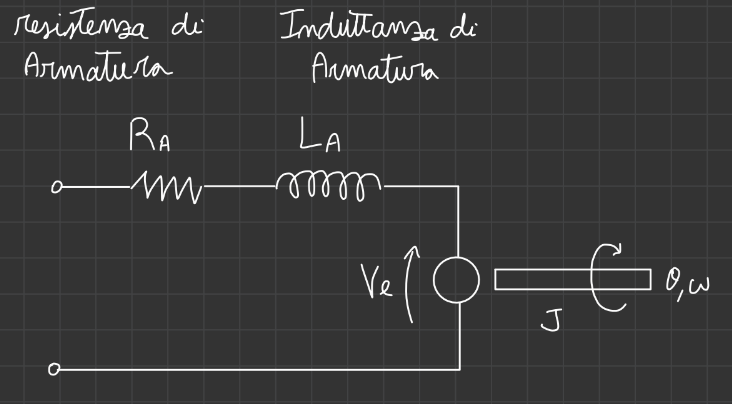

Da cui è possibile ricavare le seguenti equazioni:

- 
$$\mathrm{Ve}\left(t\right)=K_e \;\omega \left(t\right)$$


- 
$$T\left(t\right)=K_T \;i\left(t\right)$$


Con $K_e$ e $K_T$ caratteristici del motore.

### Dinamica del Motore

La dinamica del motore è caratterizzata da due equazioni


$$\left\lbrace \begin{array}{ll}
V\left(t\right)=R_A {\;i}_A \left(t\right)+L_A \;\frac{\mathrm{d}}{\mathrm{d}t}i_A \left(t\right)+\mathrm{Ve}\left(t\right) & \mathrm{Eq}\;\mathrm{Sistema}\;\mathrm{Elettrico}\\
J\;\dot{\omega} \left(t\right)=-B\;\omega \left(t\right)+T\left(t\right) & \mathrm{Eq}\;\mathrm{Sistema}\;\mathrm{Meccanico}
\end{array}\right.$$


Da queste è possibile ricavare le equazioni di accoppiamento


$$\left\lbrace \begin{array}{ll}
V\left(t\right)=R_A {\;i}_A \left(t\right)+L_A \;\frac{\textrm{d}}{\textrm{d}t}i_A \left(t\right)+K_e \;\omega \left(t\right) & \\
J\;\dot{\omega} \left(t\right)=-B\;\omega \left(t\right)+K_T \;i\left(t\right) & 
\end{array}\right.$$


Applicando la trasformata di Laplace alle prime


$$\left\lbrace \begin{array}{ll}
V\left(s\right)=R_A {\;I}_A \left(s\right)+s\;L_A \;I_A \left(s\right)+\mathrm{Ve}\left(s\right) & \\
s\;J\;\Omega \left(s\right)=-B\;\Omega \left(s\right)+T\left(s\right) & 
\end{array}\right.$$


si ricavano facilmente le seguenti formule:


$$I_A \left(s\right)=\left\lbrack V\left(s\right)-\mathrm{Ve}\left(s\right)\right\rbrack \frac{1}{s\;L_A +R_A }$$
 


$$\left\lbrack s\;J+B\right\rbrack \Omega \left(s\right)=T\left(s\right)$$


#### Implementazione in Simulink

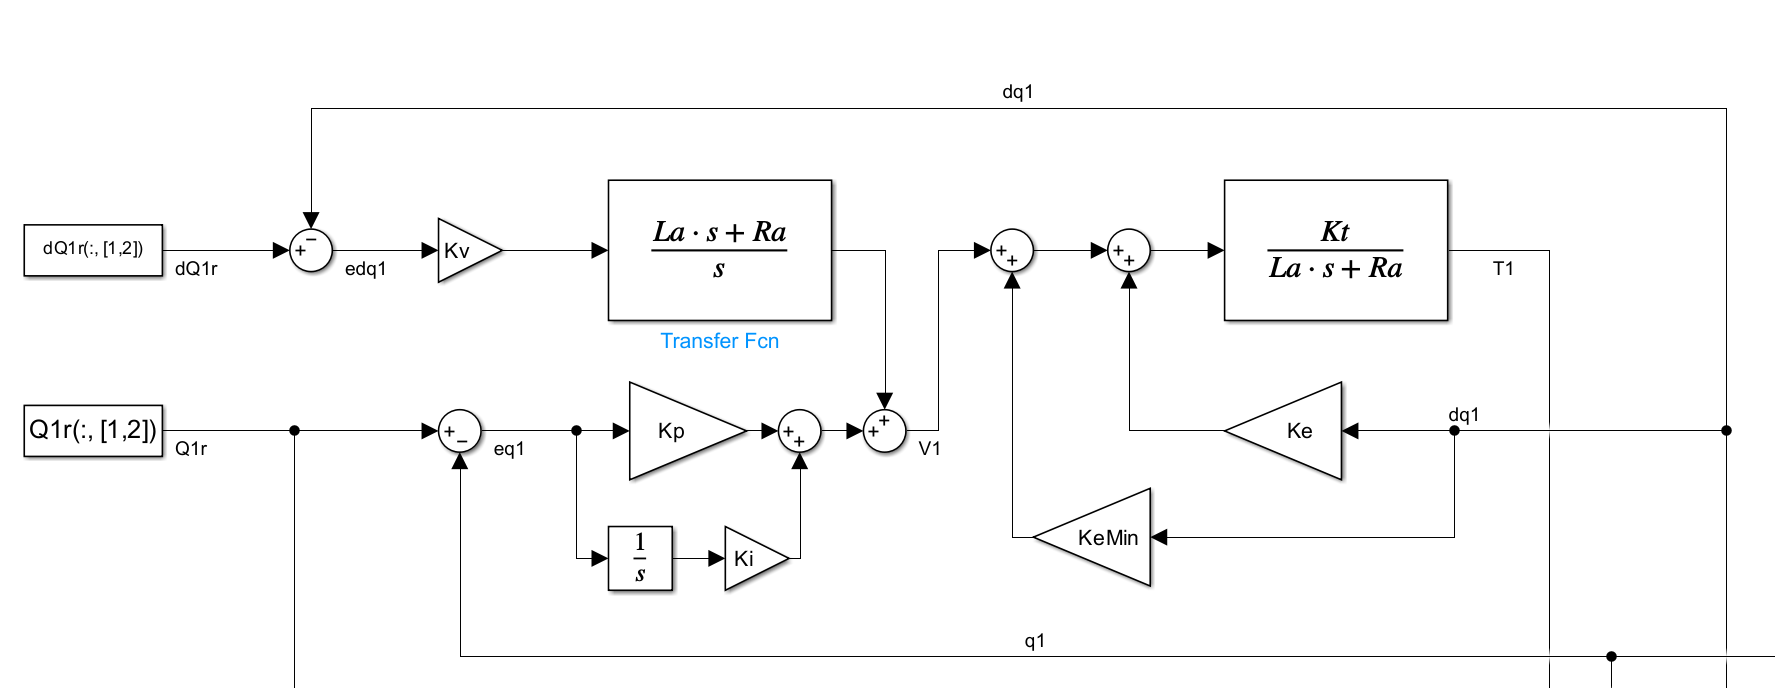

Il controllore PID stabilisce la tensione $V_A$ che deve essere erogata al motore. Successivamente i guadagni $K_T \;e\;K_e$, insieme ai valori intrinseci del motore $L_A \;e\;R_A$, viene generata la coppia $T$. Aggiungere il guadagno $K_e \;\min$ serve ad eliminare l'effetto della retroazione intrinseca del motore dovuta alla legge di Lenz.

La coppia $T$ generata sarà poi inserita in un modello dinamico che tiene conto sia dell'inerzia che dell'attrito intrinseci del mototre, ed eventualmente anche del riduttore di giri.